## Digital Communications TTT4130 - Matlab Lab Sessions

**Lab Responsible**: Johan Suarez (johan.suarez@ntnu.no)

`Prerequisites`

Up-to-date installation of `MATLAB `and `SIMULINK `including `Communications Toolbox. (NTNU students receive Campus license)`

`Instructions`

**All lab sessions are group projects. Groups will be assigned randomly and consist of 2-3 people.** 

This is a Matlab live script. The script will guide through the lab session with coding tasks accompanied by explanations and comments. The live script and the project report must be completed and delivered to BlackBoard**.**

**Please download and install MATLAB/Simulink and include the Communications toolbox as add-in. **

**You are free to use any resource you think is useful. Collaboration and discussion between groups is encouraged. **

### `Project 1`

This first lab session covers the basics of *digital communications. *The students will get an understanding of the *essential *building blocks of generic digital communication systems. In particular, the project is based on the simulation of an equivalent complex baseband representation of a passband system. 

### `Digital Communications System Schematic`

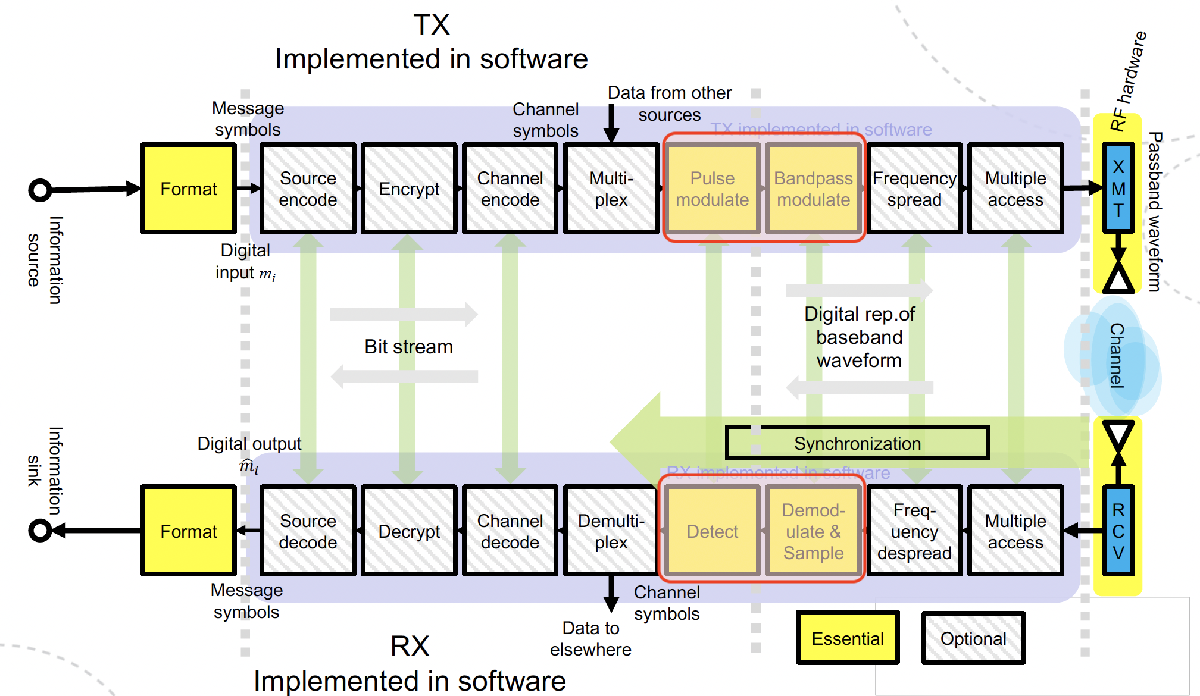

Specifically, the lab session covers the highlighted (red) parts of the schematic depicted above. 

`Course Content`

- Principles of digital communication channels

- Digital modulation schemes

- Nyquist pulse shaping 

- Matched filtering

- Additive-White-Gaussian Noise Channels

- BER vs SNR

`Bonus`

- Frame Synchronisation 

**How to use: **

**You can configure parameters of the simulated equivalent baseband digital communication system here in the livescript. Some of these parameters can be changed during simulation runtime from the **`SIMULINK `**dashboard . Running the simulation will also open other windows with plots displaying important communication system statistics.  **

#### `System Configuration`

% Symbol Rate 
symRate = 1000;         % 1/s



SNR = Simulink.Parameter(0.1)       % Signal to Noise ratio, specifically Energy per bit to Noise Power density ratio (Eb/No)

SNR =   Parameter with properties:

          Value: 0.1000
     Complexity: 'real'
     Dimensions: [1 1]
      CoderInfo: [1×1 Simulink.CoderInfo]
    Description: ''
       DataType: 'auto'
            Min: []
            Max: []
           Unit: ''


Select modulation scheme

modScheme = "BPSK"

modScheme = "BPSK"




% For M-ary QAM specify modulation order 
% NB! Make sure modOrder matches modScheme

modOrder = 2

modOrder = 2

Specify Transmit Filter Parameters

alpha =0.2  % Nyquist Filter Roll-Off Factor

alpha = 0.2000



filterLenSymbols = 10;            % Filter Length in Symbols


samplesPerSymbol = 8;             % Filter Upsampling Factor


`Task 0: Simulink Baseband Communication System`

Arrange and connect the blocks in the enclosed `Simulink `file (*CommSysSimulink.slx*) to achieve a functioning complex equivalent baseband communication simulation.

`Task 1: QPSK/BPSK Modulation`

Implement a function that perfoms digital QPSK/BPSK modulation on a frame of binary input data.

The following mapping rules apply for BPSK:


$$\begin{array}{l}
0\to 1\\
1\to -1
\end{array}$$


function symOut = BPSKmod(binIn)
%  'binIn' is a binary stream (e.g., 0100011...)



Error due to multiple causes.

Caused by:
    Error using TTT4130_Project1 (line 44)
    Complex signal mismatch. 'Input Port 1' of 'CommSysSimulink/BER/Selector' expects a signal of numeric type complex. However, it is driven by a signal of numeric type real
    Error using TTT4130_Project1 (

end


Now implement QPSK modulation according to the following specifications:

- **Gray coding with [0,1,3,2] (MSB first) starting in the first quadrant of the complex plane and proceeding in mathematical positive direction**

- **Modulated symbols must have a magnitude of 1 (signal energy) **

- **Phase offset is pi/4**

function symOut = QPSKmod(binIn)  % TEMPLATE SOLUTION
    %  'binIn' is a binary stream (e.g., 0100011...) with
    %  len(binIn)%log2(modOrder) = 0
    


end


Test your BPSK/QPSK modulation implementation by choosing the option `BPSK (Student)/QPSK (Student) `in *modScheme *- SelectionBox

Why is the modulated data complex? Explain. 

`RUN THE DIGITAL BASEBAND COMMUNICATION SYSTEM SIMULATION `

`NOTE: ``You can also open the simulink model and run it directly.`

% Simulation Time
simTime = 100;    % Change to 'inf' for indefinite runtime

% Run simulation (simulation output is stored in simout structure)
out = sim("TTT4130_Prosjekt_1/CommSysSimulink.slx",'StopTime',string(simTime),'SimulationMode', 'normal')


`Task 2: Pulse-shaping filter and matched filtering`

Plot the nyquist RRC pulse shape (rcTxFilt) for different values of the roll-off factor. How does the roll-off factor affect the spectral properties of the signal?

`Task 3: Baseband Bandwidth and Symbol Rate`

Change the symbol rate setting in the live script and observe how the baseband bandwidth of the signal changes.

Change the pulse shaping filter roll-off-factor *alpha *setting in the live script and observe how the baseband bandwidth of the signal changes.

Explain your observations and compare it to the theoretical predictions. 

How is the number of processed bits affected by the symbol rate and modulation scheme?

`Task 4: SNR vs BER`

Observe how the Bit-Error-Rate (BER) of the passband communication system changes with different configurations of the *Signal-to-Noise *ratio setting of the *Channel *block. Collect statistics for various configurations and plot SNR against BER. For BPSK and QPSK, confirm your findings with corresponding theoretical predictions (Keywords: BER, probability of error).

**Note: Statistics of SNR vs BER data are collected during the simulation and recoreded into 'out.SNRvBER'. You will need to do a little bit of data shuffling and re-organisation to do this. Tip: Inspect SNRvBER **

% Plot the SNR vs BER data

SNRvBER = squeeze(out.SNRvBER)


